optimParams_v1

Optim Params by using Surrogate optimization for an expensive optimization problems

% Load data
% load pricevolumedata.mat ;
dataInput = load("pricevolumedata.mat") ;
openpriceTT = dataInput.openpriceTT ;
highpriceTT = dataInput.highpriceTT ;
lowpriceTT = dataInput.lowpriceTT ;
closepriceTT = dataInput.closepriceTT ;
volumeTT = dataInput.volumeTT ;

% Select last nsteptrain as training data set
nsteptrain = 250*4 ;
openpriceTT = openpriceTT(end-nsteptrain+1:end,:) ;
highpriceTT = highpriceTT(end-nsteptrain+1:end,:) ;
lowpriceTT = lowpriceTT(end-nsteptrain+1:end,:) ;
closepriceTT = closepriceTT(end-nsteptrain+1:end,:) ;
volumeTT = volumeTT(end-nsteptrain+1:end,:) ;

dataInput.openpriceTT = openpriceTT ;
dataInput.highpriceTT = highpriceTT ;
dataInput.lowpriceTT = lowpriceTT ;
dataInput.closepriceTT = closepriceTT ;
dataInput.volumeTT = volumeTT ;

clear openpriceTT highpriceTT lowpriceTT closepriceTT volumeTT 


% Test objective and constraints function
optimPoint = 5;
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
paramsInput     = [70	106	5	3	8	14	107	29	4	4	6]

paramsInput =     70   106     5     3     8    14   107    29     4     4     6


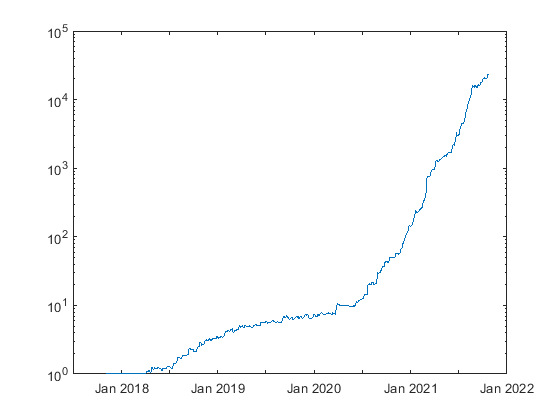

portEndValue = 2.2727e+04

portMinValue = 1

portMaxValue = 2.3267e+04

MaxDD = 0.1392

MaxDDIndex =    542
   553


drawdownDate = 2×1 datetime array
   2019-12-02
   2019-12-17


sharpeRatio = 4.8973

FortValueAtOptPoint = 2.0099e+04

PortRetOptPtEnd = 0.1308

optimPointDate = datetime
   2021-10-14


nYear = 3.9699

CAGR = 11.5142

dailyRetAvg = 0.0106

dailyRetMin = -0.1234

dailyRetMax = 0.3212

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'TCPI'}       {[1.5249]}    
    {'INAF'}       {[1.4762]}    
    {'FIRE'}       {[1.4442]}    
    {'BNBA'}       {[1.3930]}    
    {'BBHI'}       {[1.3901]}    
    {'KAEF'}       {[1.3480]}    
    {'ACST'}       {[1.3167]}    
    {'ABBA'}       {[1.3013]}    
    {'BOLA'}       {[1.2735]}    
    {'SURE'}       {[1.2349]}    
    {'FILM'}       {[1.2328]}    
    {'BBYB'}       {[1.2278]}    
    {'ZBRA'}       {[1.2217]}    
    {'MPPA'}       {[1.2209]}    
    {'FREN'}       {[1.2186]}    
    {'BABP'}       {[1.2092]}    


tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

analyzeTradeResults

Optim parameters

Define upper, lower bound and constraints

startTime = tic

startTime = uint64
1781805975952

% Define upper, lower and bound 
% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
lb              = [20   50  5   1   3   2   80  10  1   1   0] ;
ub              = [150  150 60  6   20  30  250 60  10  8   15] ;

% lb              = [60   50  5   1  2   0   60  5   3   1   0] ;
% ub              = [250  200 60  10 10  15  250 30  5   5   8] ;

% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 


% Integer constraints
nvars = 11 ;
intcon = 1:nvars ;

% Objective & constraints function
optimPoint = 5

optimPoint = 5

dataInput = load("pricevolumedata.mat") ;

% f =  @(x)objconstrFcn(x, dataInput, optimPoint);
% f =  @(x)objFcn(x, dataInput, optimPoint);
obj = @(x)objFcn(x, dataInput, optimPoint) ;
nlconst = @(x)nlconstFcn(x, dataInput, optimPoint) ;

objconstr = packfcn(obj,nlconst) ;
f = objconstr ;

% Set options
maxFcnEval = 300;
opts = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-4, "MaxFunctionEvaluations",maxFcnEval, ...
    "UseParallel", true, "UseVectorized",true);


Call `surrogateopt` to solve the problem

Objective or constraint function returned NaN.


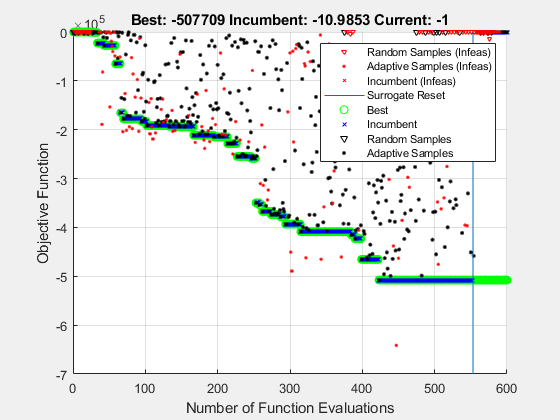

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    145    72     5     1    11     5   166    60     8     1     5


fval = -5.0771e+05

exitflag = 0

outpt = struct with fields:
        elapsedtime: 1.5637e+03
          funccount: 600
    constrviolation: -3.1881e-04
               ineq: [-3.1881e-04 -2.1908]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


% Call surrogateopt to solve the problem
% rng default % For reproducibility
[sol,fval,exitflag,outpt] = surrogateopt(f,lb,ub,intcon,opts)


endTime = toc(startTime)

endTime = 1.5659e+03

Examine result of optimized params

paramsInput     = sol

paramsInput =    145    72     5     1    11     5   166    60     8     1     5


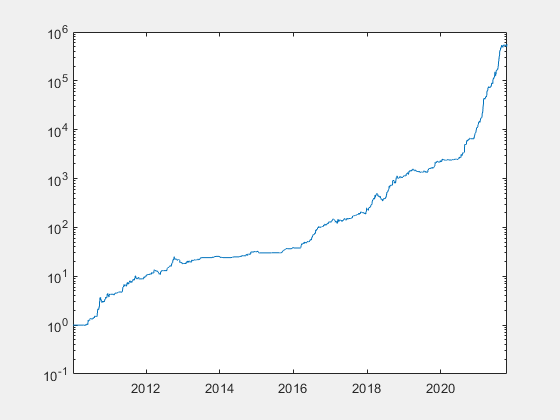

portEndValue = 5.5117e+05

portMinValue = 0.9747

portMaxValue = 5.6532e+05

MaxDD = 0.2997

MaxDDIndex =         2043
        2084


drawdownDate = 2×1 datetime array
   2018-04-10
   2018-06-06


sharpeRatio = 3.1908

FortValueAtOptPoint = 5.0771e+05

PortRetOptPtEnd = 0.0856

optimPointDate = datetime
   2021-10-14


nYear = 11.8055

CAGR = 2.0642

dailyRetAvg = 0.0048

dailyRetMin = -0.1404

dailyRetMax = 0.3813

symCumRetEndT = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'ZBRA'}       {[1.5236]}    
    {'NIKL'}       {[1.5124]}    
    {'TCPI'}       {[1.3946]}    
    {'POLY'}       {[1.3886]}    
    {'IMAS'}       {[1.3679]}    
    {'ACST'}       {[1.3531]}    
    {'BNBA'}       {[1.3101]}    
    {'SMMT'}       {[1.2985]}    
    {'FPNI'}       {[1.2834]}    
    {'MPPA'}       {[1.2791]}    
    {'IATA'}       {[1.2758]}    
    {'AGRO'}       {[1.2675]}    
    {'CLPI'}       {[1.2526]}    
    {'DMMX'}       {[1.2498]}    
    {'RAJA'}       {[1.2473]}    
    {'BOLA'}       {[1.2430]}    


CAGR = 2.0642

tradingSignalTT = tradingSignalFcnVectorized_v1 (paramsInput, dataInput) ;
[portDailyRetTT, netDailyRetperSymTT] = tradingBacktestFcn_v2 (tradingSignalTT, dataInput) ;

CAGR = analyzeTradeResults (dataInput, tradingSignalTT, portDailyRetTT, netDailyRetperSymTT, optimPoint)

Analyze the input parameters compared to its boundaries

% Examine result of optimized params
% Input parameters
% volumeMAtreshold = x(1)/100 ; % input #1 
% volumeMAlookback = x(2) ; % input #2
% valueThreshold = x(3)*10^9 ; % input #3 in Rp billion
% valueLookback = x(4) ; % input #4
% volumeValueBufferDays = x(5) ; % input #5
% priceRetLowCloseThresh = x(6)/100 ; % input #6
% priceMAThreshold = x(7)/100 ; % input #7
% priceMAlookback = x(8) ; % input #8
% priceVolumeValueBufferDays = x(9) ; % input #9
% cutlossLookback = x(10) ; % input #10
% cutlosspct = x(11)/100 ; % input #11 

% counter help  = [1    2   3   4   5   6   7   8   9   10  11]
counterhelp     = [1    2   3   4   5   6   7   8   9   10  11]

counterhelp =      1     2     3     4     5     6     7     8     9    10    11


sol

sol =    145    72     5     1    11     5   166    60     8     1     5


lb              = [20   50  5   1   3   2   80  10  1   1   0] 

lb =     20    50     5     1     3     2    80    10     1     1     0


ub              = [150  150 60  6   20  30  250 60  10  8   15] 

ub =    150   150    60     6    20    30   250    60    10     8    15


Stock picks

% Stock picks

stockpicks
